close all;
clear;

proj_folder = "C:\Users\VMORAIS\Development\20210829 - SummerSchool_proj\2. data";

if ~exist(proj_folder, 'dir')
    fprintf("Choose directory: ..\\2. data\\");
    proj_folder = uigetdir();
end


## load CSV files

%%%DEMO1
meas11 = importfile(strcat(proj_folder, "\demo1\meas11.csv"), [2, Inf]);
meas12 = importfile(strcat(proj_folder, "\demo1\meas12.csv"), [2, Inf]);
meas13 = importfile(strcat(proj_folder, "\demo1\meas13.csv"), [2, Inf]);
%meas4 = load_meas4();

%%%DEMO2
meas21 = importfile(strcat(proj_folder, "\demo2\meas21.csv"), [2, Inf]);
meas22 = importfile(strcat(proj_folder, "\demo2\meas22.csv"), [2, Inf]);
meas23 = importfile(strcat(proj_folder, "\demo2\meas23.csv"), [2, Inf]);

%%%DEMO3
meas31 = importfile(strcat(proj_folder, "\demo3\meas31.csv"), [2, Inf]);
meas32 = importfile(strcat(proj_folder, "\demo3\meas32.csv"), [2, Inf]);


## fix time vectors for each measurement

%%%DEMO1
meas11.Timestamp = ((1:1:size(meas11,1)) .* (0.1/size(meas11,1))).';
meas12.Timestamp = ((1:1:size(meas12,1)) .* (0.1/size(meas12,1))).';
meas13.Timestamp = ((1:1:size(meas13,1)) .* (0.1/size(meas13,1))).';

%%%DEMO2
meas21.Timestamp = ((1:1:size(meas21,1)) .* (0.1/size(meas21,1))).';
meas22.Timestamp = ((1:1:size(meas22,1)) .* (0.1/size(meas22,1))).';
meas23.Timestamp = ((1:1:size(meas23,1)) .* (0.1/size(meas23,1))).';

%%%DEMO3
meas31.Timestamp = ((1:1:size(meas31,1)) .* (0.1/size(meas31,1))).';
meas32.Timestamp = ((1:1:size(meas32,1)) .* (0.1/size(meas32,1))).';


## plot measurements

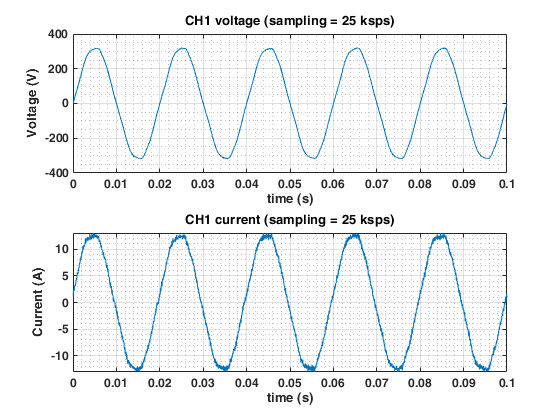

%%DEMO1
figure;
data2plot = meas13;
subplot(2,1,1);
plot(data2plot.Timestamp, data2plot.V_ch1);
grid on; grid minor; xlabel('time (s)'); ylabel("Voltage (V)"); title("CH1 voltage (sampling = 25 ksps)");
subplot(2,1,2);
plot(data2plot.Timestamp, data2plot.V_ch2);  %%% V_ch2 is current measurement
grid on; grid minor; xlabel('time (s)'); ylabel("Current (A)"); title("CH1 current (sampling = 25 ksps)"); 

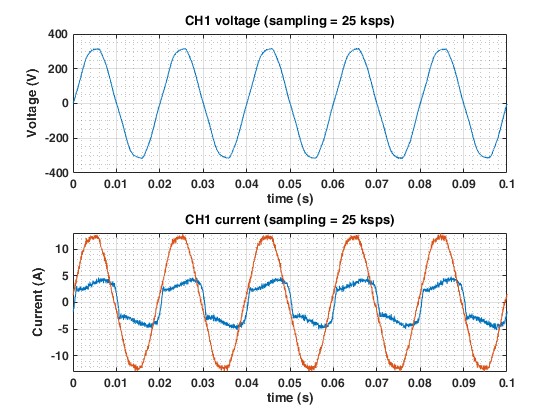


%%DEMO2
figure;
data2plot = meas21;
subplot(2,1,1);
plot(data2plot.Timestamp, data2plot.V_ch1);
grid on; grid minor; xlabel('time (s)'); ylabel("Voltage (V)"); title("CH1 voltage (sampling = 25 ksps)");
subplot(2,1,2);
plot(data2plot.Timestamp, data2plot.V_ch2);  %%% V_ch2 is current measurement
hold on;
plot(data2plot.Timestamp, data2plot.V_ch3);  %%% V_ch2 is current measurement
grid on; grid minor; xlabel('time (s)'); ylabel("Current (A)"); title("CH1 current (sampling = 25 ksps)"); 

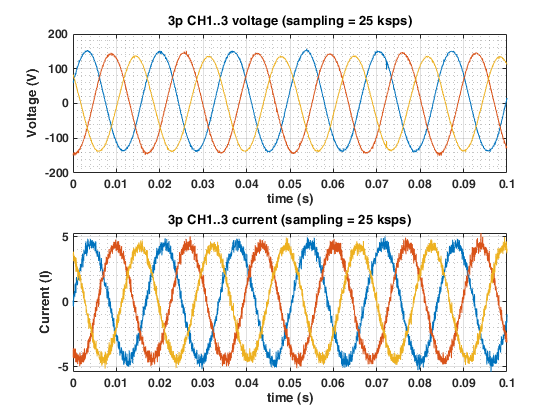


%%%DEMO3
figure;
data2plot = meas32;
subplot(2,1,1);
plot(data2plot.Timestamp, data2plot.V_ch1);
hold on;
plot(data2plot.Timestamp, data2plot.V_ch2);
plot(data2plot.Timestamp, data2plot.V_ch3);
grid on; grid minor; xlabel('time (s)'); ylabel("Voltage (V)"); title("3p CH1..3 voltage (sampling = 25 ksps)");
subplot(2,1,2);
plot(data2plot.Timestamp, data2plot.I_ch1);
hold on;
plot(data2plot.Timestamp, data2plot.I_ch2);
plot(data2plot.Timestamp, data2plot.I_ch3);
grid on; grid minor; xlabel('time (s)'); ylabel("Current (I)"); title("3p CH1..3 current (sampling = 25 ksps)");

function meas = load_meas4()
    proj_folder = "C:\Users\VMORAIS\Development\20210829 - SummerSchool_proj\2. data\demo1\meas4\meas4_00";
    
    meas = importfile(strcat(proj_folder, num2str(1), ".csv"), [2, Inf]);
    meas.Timestamp = ((1:1:size(meas,1)) .* (0.1/size(meas,1))).';
    for it=2:9
        meas_aux = importfile(strcat(proj_folder, num2str(it), ".csv"), [2, Inf]);
        meas_aux.Timestamp = meas.Timestamp(end) + ((1:1:size(meas_aux,1)) .* (0.1/size(meas_aux,1))).';
        meas = [meas; meas_aux];
    end
    meas_aux = importfile("C:\Users\VMORAIS\Development\20210829 - SummerSchool_proj\2. data\demo1\meas4\meas4_010", [2, Inf]);
    meas_aux.Timestamp = meas.Timestamp(end) + ((1:1:size(meas_aux,1)) .* (0.1/size(meas_aux,1))).';
    meas = [meas; meas_aux];
end

function meas1 = importfile(filename, dataLines)
%IMPORTFILE Import data from a text file
%  MEAS1 = IMPORTFILE(FILENAME) reads data from text file FILENAME for
%  the default selection.  Returns the data as a table.
%
%  MEAS1 = IMPORTFILE(FILE, DATALINES) reads data for the specified row
%  interval(s) of text file FILENAME. Specify DATALINES as a positive
%  scalar integer or a N-by-2 array of positive scalar integers for
%  dis-contiguous row intervals.
%
%  Example:
%  meas1 = importfile("C:\Users\VMORAIS\Development\20210829 - SummerSchool_proj\2. data\demo1\meas1.csv", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 29-Aug-2021 16:43:08

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Timestamp", "V_ch1", "V_ch2", "V_ch3", "I_ch1", "I_ch2", "I_ch3"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
meas1 = readtable(filename, opts);

end